


syms V x
d = 2;
R = 2.5;
V = [];
x = 0.2:0.001:5

x =     0.2000    0.2010    0.2020    0.2030    0.2040    0.2050    0.2060    0.2070    0.2080    0.2090    0.2100    0.2110    0.2120    0.2130    0.2140    0.2150    0.2160    0.2170    0.2180    0.2190    0.2200    0.2210    0.2220    0.2230    0.2240    0.2250    0.2260    0.2270    0.2280    0.2290    0.2300    0.2310    0.2320    0.2330    0.2340    0.2350    0.2360    0.2370    0.2380    0.2390    0.2400    0.2410    0.2420    0.2430    0.2440    0.2450    0.2460    0.2470    0.2480    0.2490


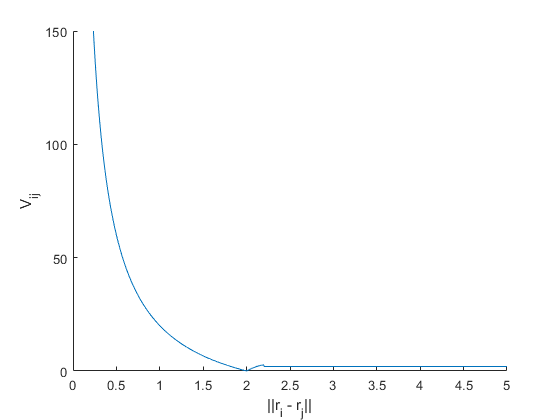


figure; hold on
for i = 1:4801
      
    if (x(:,i)<=d)
       V(:,i) =  -(20*(x(:,i)-d)/(x(:,i)));
      
    end
    if (x(:,i)>d) && (x(:,i)<R-0.3)
        V(:,i) =  (2*pi*(sin(2*pi*(x(:,i)-d)))/x(:,i));
        
    end
    
    if (x(:,i)>=R-0.3)
        V(:,i) = 2;
    end
    
end

plot(x,V)
xlim([0 5])
ylim([0 150])
xlabel('||r_{i} - r_{j}||') 
ylabel('V_{ij}') 

%this is the condition of the first potential function proposed in equation 36

syms V x
d = 2;
R = 2.5;
V = [];
x = 0.4:0.001:2.5

x =     0.4000    0.4010    0.4020    0.4030    0.4040    0.4050    0.4060    0.4070    0.4080    0.4090    0.4100    0.4110    0.4120    0.4130    0.4140    0.4150    0.4160    0.4170    0.4180    0.4190    0.4200    0.4210    0.4220    0.4230    0.4240    0.4250    0.4260    0.4270    0.4280    0.4290    0.4300    0.4310    0.4320    0.4330    0.4340    0.4350    0.4360    0.4370    0.4380    0.4390    0.4400    0.4410    0.4420    0.4430    0.4440    0.4450    0.4460    0.4470    0.4480    0.4490


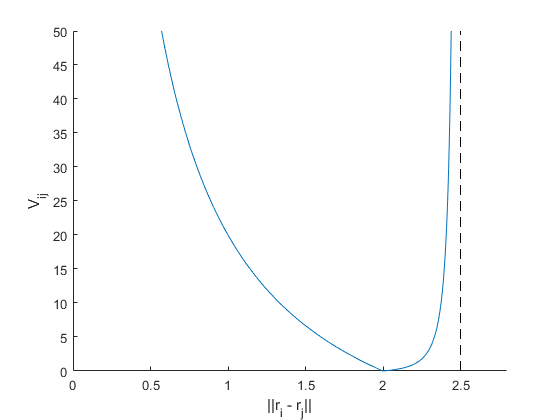


figure; hold on
for i = 1:2101
    if (x(:,i)<=d)
       V(:,i) =  (-20*(x(:,i)-d)/(x(:,i)));
      
    end
    if (x(:,i)>d) && (x(:,i)<=R)
        V(:,i) =  ((x(:,i)-d)/(x(:,i)*(x(:,i)-R)^2));
        
    end
    
end


plot(x,V);
xlim([0 2.8]);
ylim([0 50]);
hold on

plot([2.5,2.5],[0,50], 'k--')
xlabel('||r_{i} - r_{j}||') 
ylabel('V_{ij}') 